# Documentation for the Matlab codes

This is a live script accompaying our paper L. Adam, X. Yao: A Simple Yet Effective Approach to Robust Optimization Over Time. We show a simple example of how to use our code. In the few lines, we will generate the dynamics for the moving peaks benchmark, propose a simple optimization method and evaluate its performance.

First, set a random seed so that we all can see the same results.

rng(500);

Now we will initalize the options `opts`. After that we will run the evolution to get the peak heights `h`, widths `w` and centers `c`. Note that these variables store the whole future. When you run optimization, you should look only at the present or past values but never at the future.

file_name = 'Default1';
opts      = Initialize_Options(file_name);
[h, w, c] = Compute_Evolution(opts);

Let us design a simple method. We know that the lower and upper bounds for the decision variable are `opts.x_min` and `opts.x_max`, respectively. We generate `opts.n_eval` random points `x` and evaluate them. At every time instant `t` we select the points which has the largest objective and store it in `x_opt`. Note that for selection of these points we did not utilize the future values.

x = opts.x_min + (opts.x_max - opts.x_min)*rand(opts.n_eval, opts.d);

x_opt = zeros(opts.T, opts.d);
for t=1:opts.T
    val        = opts.F_eval(t, x, h, w, c);
    [~,i_max]  = max(val);
    x_opt(t,:) = x(i_max,:);
end

To evaluate the performance, we first compure the function values at the next `T_range=20` time instants.

T_range = 30;
val     = zeros(opts.T, T_range);
for t=1:opts.T
    for s=1:T_range
        val(t,s) = opts.F_eval(t+s-1, x_opt(t,:), h, w, c);
    end    
end

For the averaging window `S=4` and the threshold `delta=40`, we compute the averaged and survival metrics and plot the graphs.

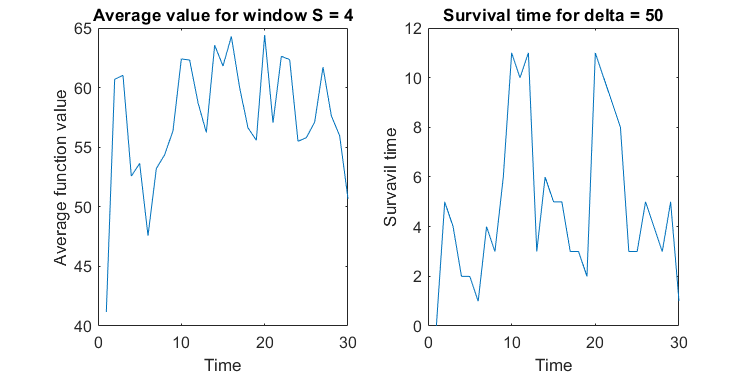

S     = 4;
delta = 50;
[F_average, F_survival] = Compute_Metrics(val, S, delta);

figure('position', [0, 0, 600, 300]);
subplot(1,2,1);
plot(1:opts.T, F_average);
xlabel('Time');
ylabel('Average function value');
title(sprintf('Average value for window S = %d', S));

subplot(1,2,2);
plot(1:opts.T, F_survival);
xlabel('Time');
ylabel('Survavil time');
title(sprintf('Survival time for delta = %d', delta));

We finish with a simple comparison. We fix time instant `time_start=10` and evaluate all points `x` at this and `T_range` following time instants. Note that we can evaluate all `x` by one function call. Then we compute the function value at the current time `F_current` and the averaged function value `F_average` for `S=4`. We see that the correlation between them is extremely high, over 95%. This implies that selecting a solution which performs well now, likely results in a solution which performs well in the future.

t_start = 10;
val     = zeros(opts.n_eval, T_range);
for s=1:T_range
    val(:,s) = opts.F_eval(t_start+s-1, x, h, w, c);
end
F_current = val(:,1);
F_average = Compute_Metrics(val(:,t_start:end), S);

correlation = corr(F_current, F_average)

correlation = 0.9555